# Estimation, Filtering and Detection

## Homework 3B: Current Sensor Fault

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

% Design healthy (m=1) state-space model
% Design faulty  (m=2) state-space model
% Find controller gain K_p to keep current limited to 200 A and no
% overshoot
% Analyze observability of m1
% Analyze observability of m2

% Motor parameters
R = 0.1;                % Ohms
L = 0.5;                % Henrys
Kt = 0.5;               % torque constant
Km = 0.5;               % motor constant
Bm = 0.0011;            % Nms/rad viscous friction
J = 10;                 % kg.m^2/s^2

% Healthy system m=1

A = [-Bm/J Kt/J; -Km/L -R/L];
B = [0 0; 1/L -1/L];
C = [1 0;0 1];
D = 0;
sys_healthy = ss(A,B,C,D);

% Faulty system m=2

A_f = [-Bm/J Kt/J; -Km/L -R/L];
B_f = [0 0; 1/L -1/L];
C_f = [1 0;0 0];
D_f = 0;
sys_faulty = ss(A_f,B_f,C_f,D_f);

% Observability
disp("Observability of healthy system")

Observability of healthy system


Ob_healthy = obsv(A,C);
unobsv = length(A) - rank(Ob_healthy)

unobsv = 0

disp("Observability of faulty system")

Observability of faulty system


Ob_faulty = obsv(A_f,C_f);
unobsv = length(A_f) - rank(Ob_faulty)

unobsv = 0

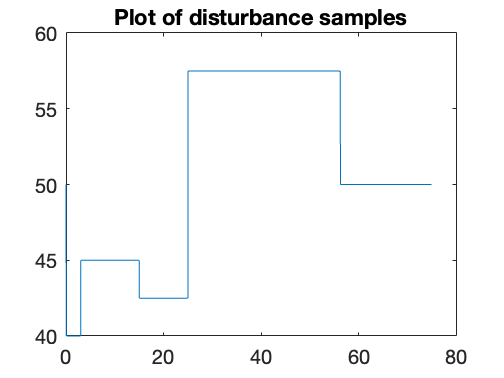




% disturbance
Ts = 0.05;
N = 1500;
T = Ts*N;
t = 0:Ts:T;
load = 50;        % Nm
deviation = 10;
Td = load*ones(1,N); % load disturbance
for i=1:N
    if i<=N/25
        Td(i) = Td(i) - deviation;
    end
    if i>N/25 && i<=N/5
        Td(i) = Td(i) - deviation/2;
    end
    if i>N/5 && i<=N/3
        Td(i) = Td(i) - 3*deviation/4;
    end
    if i>N/3 && i<=3*N/4
        Td(i) = Td(i) + 3*deviation/4;
    end
end
Td = [load Td];
figure;
plot(t,Td);
title("Plot of disturbance samples");

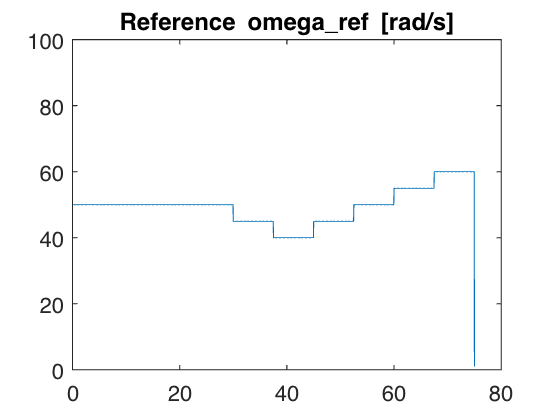


% refference signal
w_ref = ones(size(t));
for i=1:N
    if i<=N/10
        w_ref(i) = 50;
    end
    if i>N/10 && i<=2*N/10
        w_ref(i) = 50;
    end
    if i>2*N/10 && i<=3*N/10
        w_ref(i) = 50;
    end
    if i>3*N/10 && i<=4*N/10
        w_ref(i) = 50;
    end
    if i>4*N/10 && i<=5*N/10
        w_ref(i) = 45;
    end
    if i>5*N/10 && i<=6*N/10
        w_ref(i) = 40;
    end
    if i>6*N/10 && i<=7*N/10
        w_ref(i) = 45;
    end
    if i>7*N/10 && i<=8*N/10
        w_ref(i) = 50;
    end
    if i>8*N/10 && i<=9*N/10
        w_ref(i) = 55;
    end
    if i>9*N/10 && i<=N
        w_ref(i) = 60;
    end
end
figure();
plot(t,w_ref);
ylim([0 100]);
title("Reference omega\_ref [rad/s]");



u = [50*ones(1,length(Td));zeros(1,length(Td))];
% Kp = 1; % 0.01
Ki = 0.075;
Kp = 0.25;
Kd = 1.5;
% C_contr = tf(Kp);                 % P controller
% C_contr = tf([Kp Ki],[1 0])      % PI controller
C_contr = tf([Kd Kp Ki],[1 0])      % PID controller

C_contr =
 
  1.5 s^2 + 0.25 s + 0.075
  ------------------------
             s
 
Continuous-time transfer function.



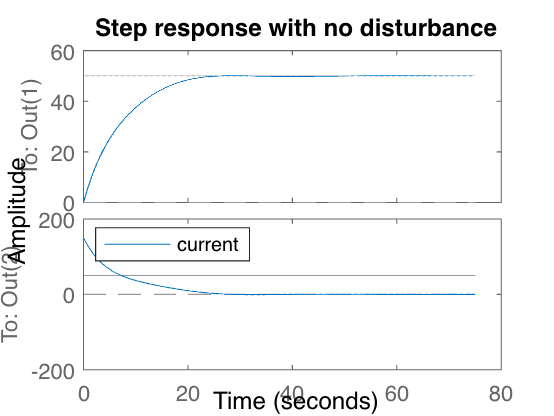

% C_contr = tf(Ki,[1 0]);           % compensator K/s

cl = feedback(sys_healthy * append(C_contr,1),1,1,1);
h = lsimplot(cl,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('Step response with no disturbance')
legend('current','Location','NorthWest')
ylim([-200 200])

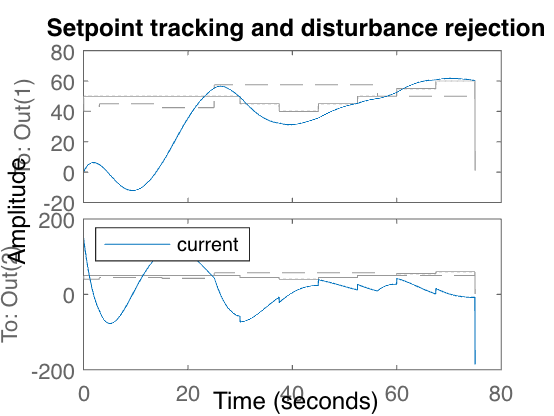


u = [w_ref ; Td];     
cl = feedback(sys_healthy * append(C_contr,1),1,1,1);
h = lsimplot(cl,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('Setpoint tracking and disturbance rejection')
legend('current','Location','NorthWest')
ylim([-200 200])

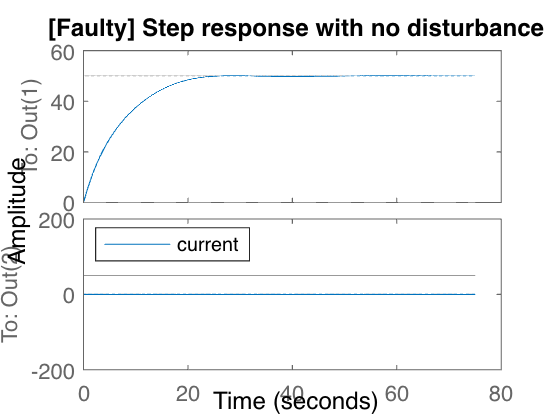


u = [50*ones(1,length(Td));zeros(1,length(Td))];
cl = feedback(sys_faulty * append(C_contr,1),1,1,1);
h = lsimplot(cl,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('[Faulty] Step response with no disturbance')
legend('current','Location','NorthWest')
ylim([-200 200])

## Problem 2:

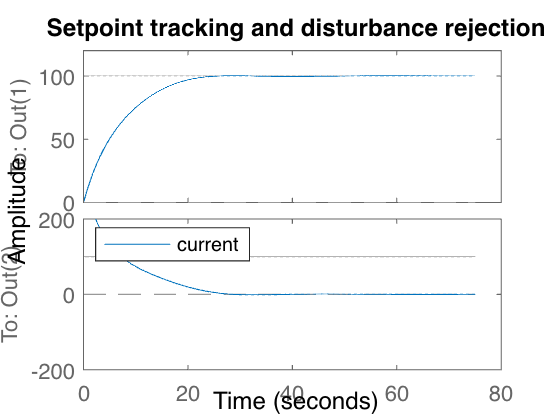

% Select and justify process noise properties
% Find input-output data with multiple sensor faults
% input = 
u = [100*ones(1,length(Td));zeros(1,length(Td))];
% u = [w_ref ; Td];


cl_healthy = feedback(sys_healthy * append(C_contr,1),1,1,1);
h = lsimplot(cl_healthy,u,t);
title('Setpoint tracking and disturbance rejection')
legend('current','Location','NorthWest')
ylim([-200 200])

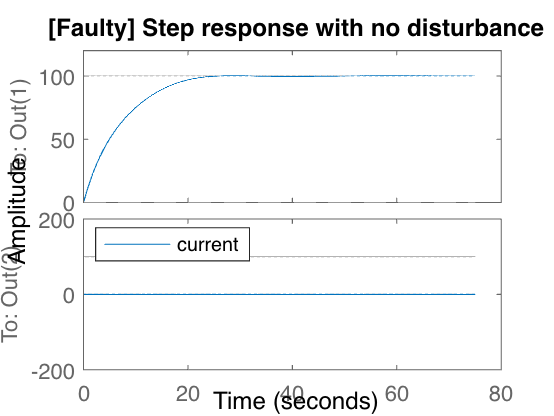



cl_faulty = feedback(sys_faulty * append(C_contr,1),1,1,1);
h = lsimplot(cl_faulty,u,t);
title('[Faulty] Step response with no disturbance')
legend('current','Location','NorthWest')
ylim([-200 200])

n_samples = length(u);
% cld_healthy = c2d(sys_healthy,Ts,'tustin');
% cld_faulty  = c2d(sys_faulty,Ts,'tustin');

% noise properties
Qc = 0.01; % selected as 10 times lower than measurement noise
Rc = 0.1;
etta = 1; % selected as 1 (Tc=0) for synchronous sampling purposes

% healthy
Ah = expm(A*Ts);
Bh = inv(A)*(expm(A*Ts)-expm(A*0))*B;
Ch = C*expm(A*etta*Ts);
Dh = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;

Qh = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
Sh = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
Rh = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

% faulty
Af = expm(A_f*Ts);
Bf = inv(A_f)*(expm(A_f*Ts)-expm(A_f*0))*B_f;
Cf = C_f*expm(A_f*etta*Ts);
Df = C_f*inv(A_f)*(expm(A_f*etta*Ts)-expm(A_f*0))*B_f;

Qf = Qc*inv(A_f+A_f')*(expm((A_f+A_f')*Ts) -expm((A_f+A_f')*0));
Sf = Qc*inv(A_f+A_f')*(expm((A_f+A_f')*etta*Ts) -expm((A_f+A_f')*0))*C_f';
Rf = Rc + C_f*Qc*inv(A_f+A_f')*(expm((A_f+A_f')*etta*Ts) -expm((A_f+A_f')*0))*C_f';


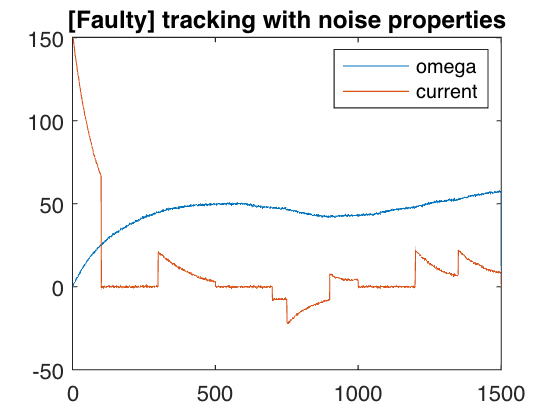

x = zeros(2,n_samples);
y = zeros(2,n_samples);
integral = 0;
last_error = 0;
% w_ref = 50*ones(size(t));
for i=1:(n_samples-1)
    error = (w_ref(i) - x(1,i));
    integral = integral + error*Ts; 
    u(:,i) = [Kp*error+Ki*integral + Kd*(error - last_error)/Ts;0];
    if ((i>100) && (i<300))||((i>500) && (i<700))||((i>1000) && (i<1200))
        % faulty
        x(:,i+1) = Af*x(:,i) + Bf*u(:,i) + sqrtm(Qh)*randn(2, 1);
        y(:,i)   = Cf*x(:,i) + Df*u(:,i) + sqrtm(Rh)*randn(2, 1);
    else
        % normal
        x(:,i+1) = Ah*x(:,i) + Bh*u(:,i) + sqrtm(Qf)*randn(2, 1);
        y(:,i)   = Ch*x(:,i) + Dh*u(:,i) + sqrtm(Rf)*randn(2, 1);
    end
    last_error = error;
end
figure();
plot(y(1,:));
hold on
plot(y(2,:));
legend("omega","current")
title("[Faulty] tracking with noise properties")
hold off

## Problem 3:

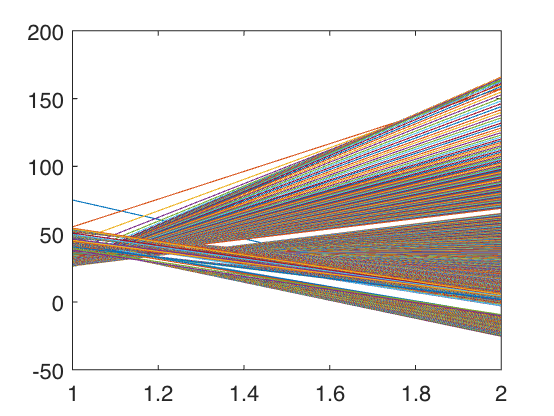

% Design IMM algorithm
% Evaluate unmeasurable load
% Detect faults of current sensor
% p12 = 0.001 transition to fault
% p21 = 0.005 recovery
pCorr = eye(2);
transProb = [0.001,0.005];

xCorrStored = zeros(2,length(y(1,:)));
for i = 1:length(y(1,:))
    detection_h = objectDetection(i,y(2,i));
    detection_f = objectDetection(i,0);
    filter = {initcvkf(detection_h),initcvkf(detection_f)};
    imm = trackingIMM('State',x(:,i),'StateCovariance',pCorr,'TransitionProbabilities', transProb,'TrackingFilters',filter,'ModelConversionFcn',@switchimm);
    [xPred,pPred] = predict(imm,Ts);
    meas = y(2,i);
    [xCorr,pCorr] = correct(imm,meas);
    xCorrStored(:,i) = xCorr;
end

figure;
plot(xCorrStored(1,:));
figure;
plot(xCorrStored(2,:));

## Problem 4:

% Analyze the performance of detection
% Compare IMM to KF using only rotation speed sensor
% Is it possible to jsutify use of current sensor?

## Problem 5:

% Lessons learned

## Additional tools

% Storing figures
if storeFigures
    for i=1:10
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end

## Functions

function [x_kk] = StateTransitionFcnHealthy(x)
    % Motor parameters
    R = 0.1;                % Ohms
    L = 0.5;                % Henrys
    Kt = 0.5;               % torque constant
    Km = 0.5;               % motor constant
    Bm = 0.0011;            % Nms/rad viscous friction
    J = 10;                 % kg.m^2/s^2
    Ts = 0.05;

    A = [-Bm/J Kt/J; -Km/L -R/L];
    Ah = expm(A*Ts);
    x_kk = Ah*x;
end
function [x_kk] = StateTransitionFcnFaulty(x)
    % Motor parameters
    R = 0.1;                % Ohms
    L = 0.5;                % Henrys
    Kt = 0.5;               % torque constant
    Km = 0.5;               % motor constant
    Bm = 0.0011;            % Nms/rad viscous friction
    J = 10;                 % kg.m^2/s^2
    Ts = 0.05;

    A_f = [-Bm/J Kt/J; -Km/L -R/L];
    Af = expm(A_f*Ts);
    x_kk = Af*x;
end